**Logistic Regression**

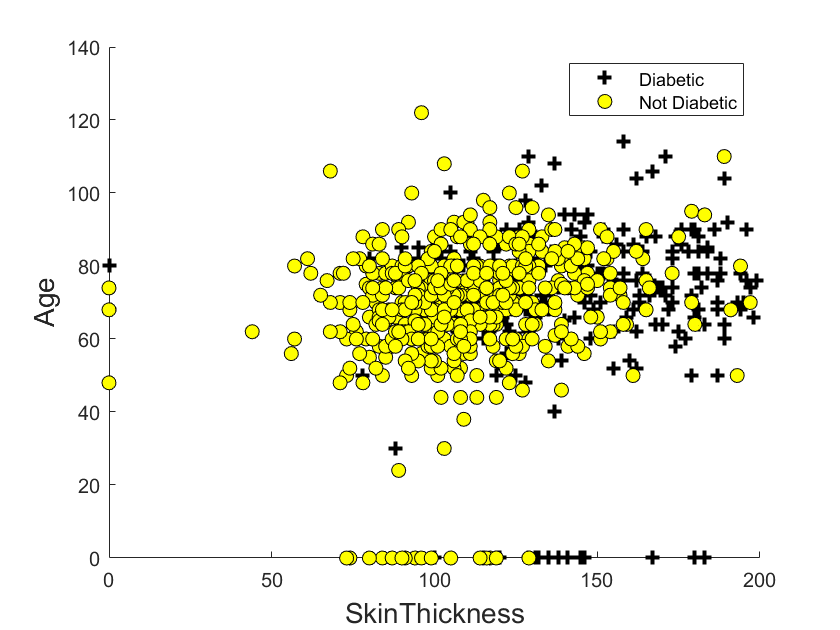

clear all
close all
% The first two columns contain the exam scores and the third column contains the label.
%data = load('ex2data1.txt');
data = csvread('diabetes2D.csv',1,0);
X = data(:, [1, 2]); 
y = data(:, 3);

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
% Labels and Legend
%xlabel('Exam 1 score','FontSize',14)
xlabel('SkinThickness','FontSize',14)
%ylabel('Exam 2 score','FontSize',14)
ylabel('Age','FontSize',14)
% Specified in plot order
%legend('Admitted', 'Not admitted')
legend('Diabetic', 'Not Diabetic')

**Initialize the data**

%  Setup the data matrix appropriately
[m, n] = size(X);
% Add intercept term to X
X = [ones(m, 1) X];
% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

**Compute the gradient**

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); 

Gradient at initial theta (zeros):


disp(grad);

    0.1510   11.1543    9.8379




% Compute and display cost and gradient with non-zero theta
test_theta = [-24; 0.2; 0.2];
[cost, grad] = costFunction(test_theta, X, y);
fprintf('\nCost at non-zero test theta: %f\n', cost);


Cost at non-zero test theta: 7.770873


disp('Gradient at non-zero theta:'); disp(grad);

Gradient at non-zero theta:
    0.6112   68.5400   43.5333



Using `fminunc`` for l`earning parameters 

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);
%  Run fminunc to obtain the optimal theta

%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.526429


disp('theta:');disp(theta);

theta:
   -5.2630
    0.0380
   -0.0016



Plotting logisitic regression **boundary** 

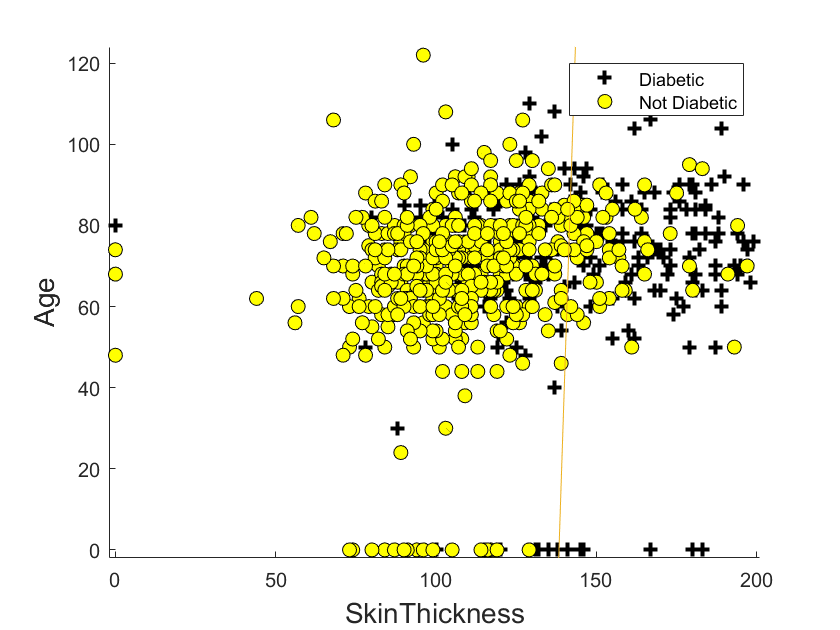

% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
%xlabel('Exam 1 score')
xlabel('SkinThickness','FontSize',14)
%ylabel('Exam 2 score')
ylabel('Age','FontSize',14)
% Specified in plot order
%legend('Admitted', 'Not admitted')
legend('Diabetic', 'Not Diabetic')
hold off;

Make **predicition**

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
%prob = sigmoid([1 45 85] * theta);
%fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);
%  Predict probability for a diabetice with age 65  and skin thikness 35  
prob = sigmoid([1 65 35] * theta);
fprintf('For a student with scores 45 and 85, we predict diabetic probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict diabetic probability of 0.054953



% Compute accuracy on our training set
p = predict(theta, X);
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 74.609375


Regularized **logistic** regression

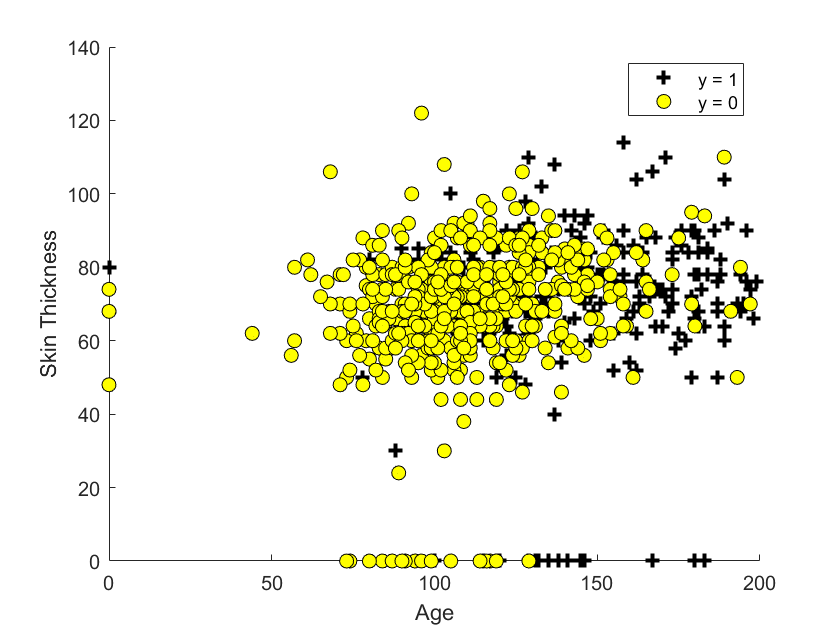

clear all
close all
%  The first two columns contains the X values and the third column
%  contains the label (y).
%data = load('ex2data1.txt');
data = csvread('diabetes2D.csv',1,0);
%data = csvread('diabetes2.csv',1,0);
X = data(:, [1, 2]); y = data(:, 3);
%X = data(:, [1:8]); y = data(:, 9);
plotData(X, y); %2D Plot for representation
%plotData(X(:,2:3), y);
% Put some labels 
hold on;
% Labels and Legend
%xlabel('Microchip Test 1')
%ylabel('Microchip Test 2')
xlabel('Age')
ylabel('Skin Thickness')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

Feature mapping

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);
% Introducing more features for better mapping
X = mapFeature(X(:,1), X(:,2));

Cost function and gradient

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);
% Set regularization parameter lambda to 1
lambda = 1;
fprintf('Cost at initial theta (zeros): %f\n');

Cost at initial theta (zeros): 

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);
fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


Learning parameters using `fminunc`

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);
lambda = 1;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);
% Advanced Optimizer
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


Plotting decision boundary

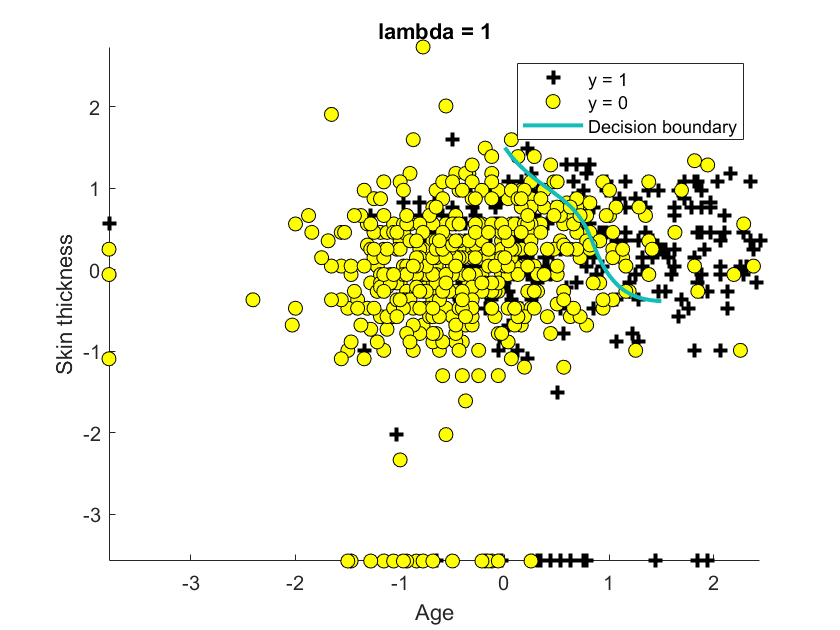

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
%xlabel('Microchip Test 1')
%ylabel('Microchip Test 2')

xlabel('Age')
ylabel('Skin thickness')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;

Prediction and Train Accuracy

% Compute accuracy on our training set
p = predict(theta, X); % p give the logic of 1 or 0 depending on learnt theta
% Computing the model accuracy
fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 74.609375
